## RR Target Simulation

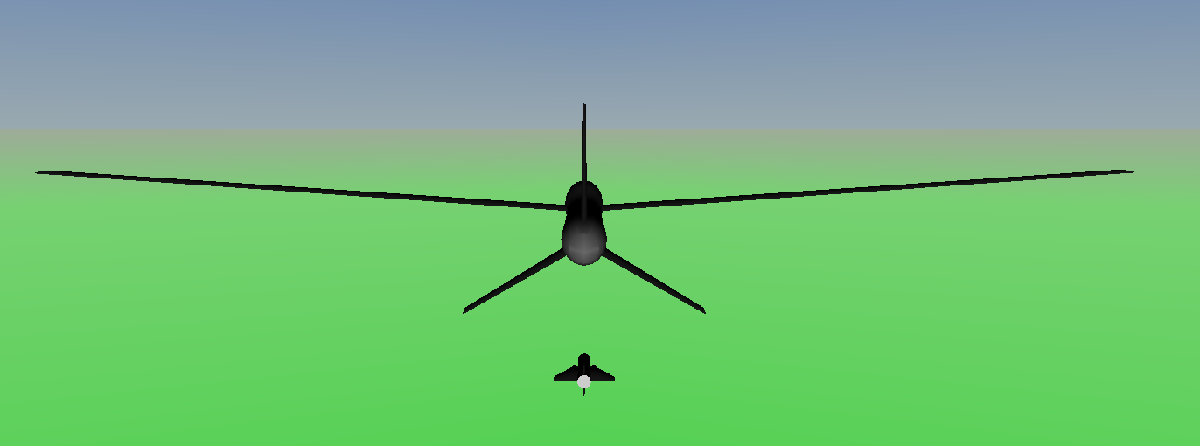

### English units

This simulation uses English units.

### Simulation Parameters

The simulation as described in "RR Target Simulation Model Design" was run using the model data and simulation parameters. The simulation starts as target vehicle passes overhead at 290 knots at 20,000 feet and the RR vehicle launches vertically from the ground after the target is down range. Because the RR vehicle simulation uses wind forces, some small initial velocity was required although in reality it would launch from zero velocity.

clear;
load("RR.mat"); 
load("target_sim.mat"); 

### Time to target


%simulation time
max(target_sim_out.tout)

ans = 55.3649

It takes less than a minute for the RR vehicle to reach the target.

### Range

% max range
max(target_sim_out.yout{3}.Values.Data(:,[1]))

ans = 2.0026e+04

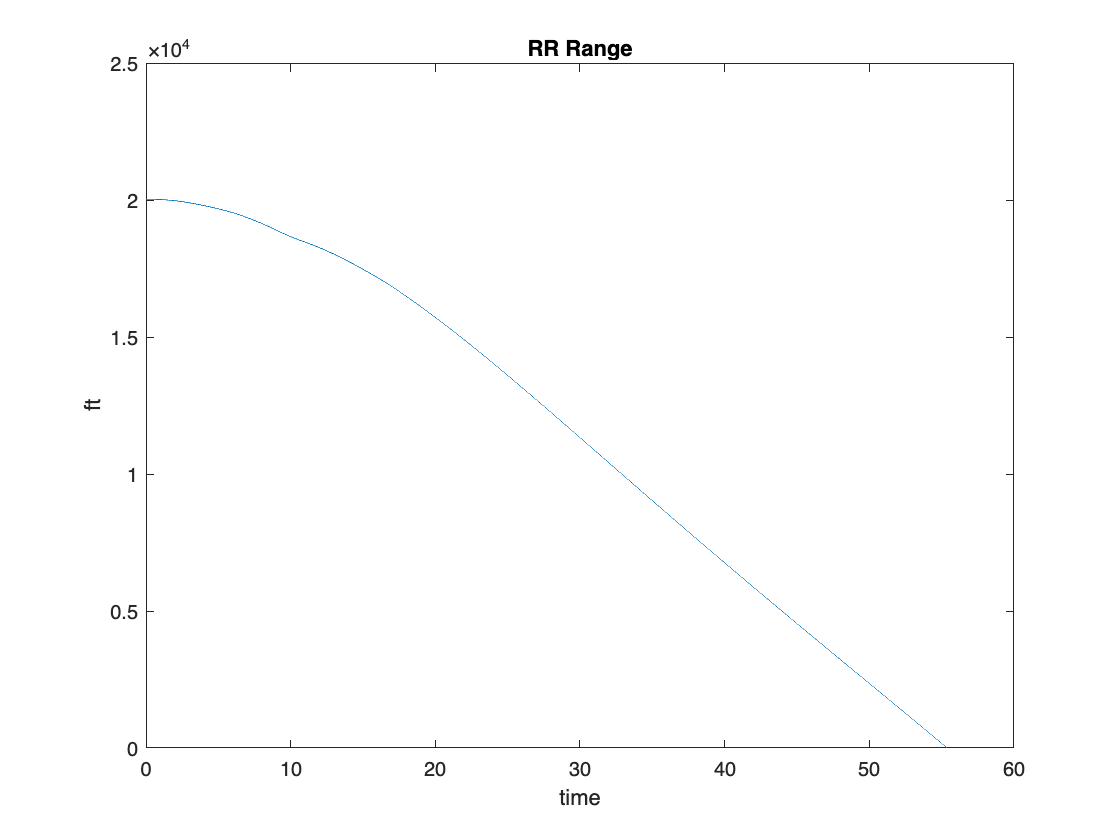

plot(target_sim_out.yout{3}.Values.Time, ...
    target_sim_out.yout{3}.Values.Data(:,[1])');
title('RR Range');
xlabel('time');
ylabel("ft")

### Position

% max down range
max(target_sim_out.yout{1}.Values.Data(:,[1]))

ans = 2.8099e+04

The target vehicle intercept happens 28,100 ft down range.

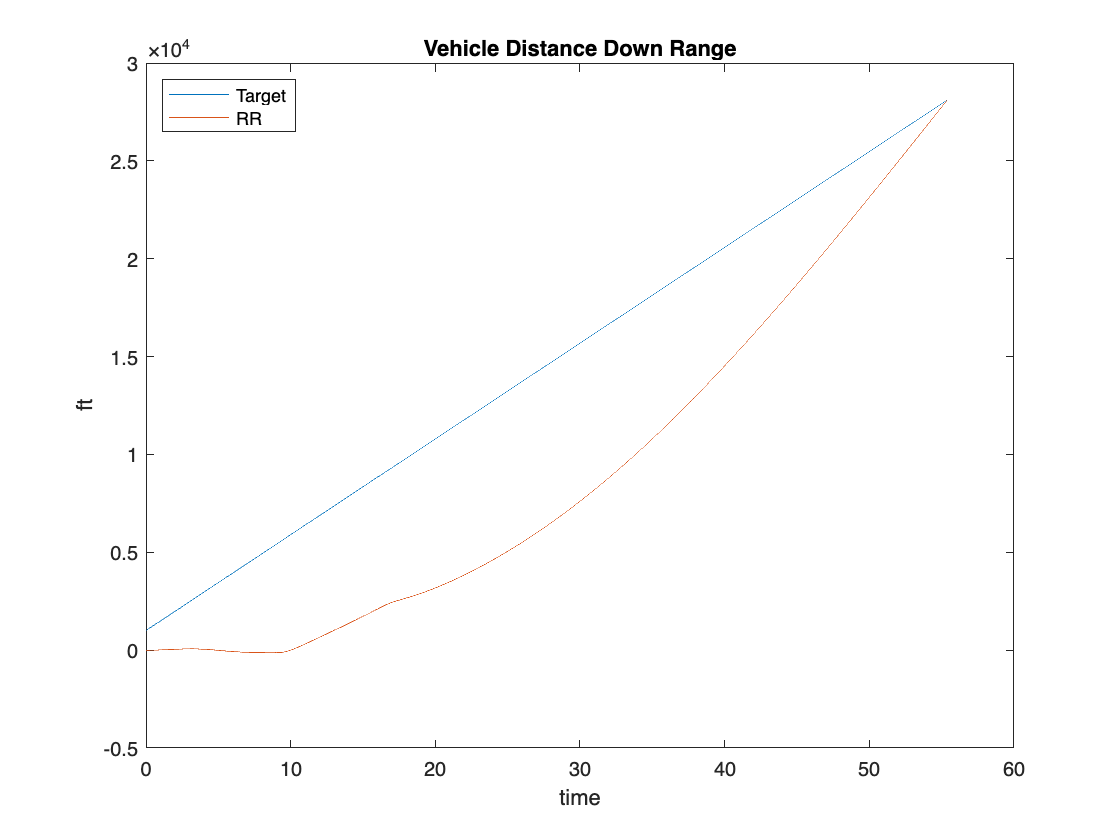

plot(target_sim_out.yout{1}.Values.Time, ...
    target_sim_out.yout{1}.Values.Data(:,[1])', ...
    target_sim_out.yout{2}.Values.Time, ...
    target_sim_out.yout{2}.Values.Data(:,[1])');
title('Vehicle Distance Down Range');
xlabel('time');
ylabel("ft");
legend({'Target','RR'},'Location','northwest');

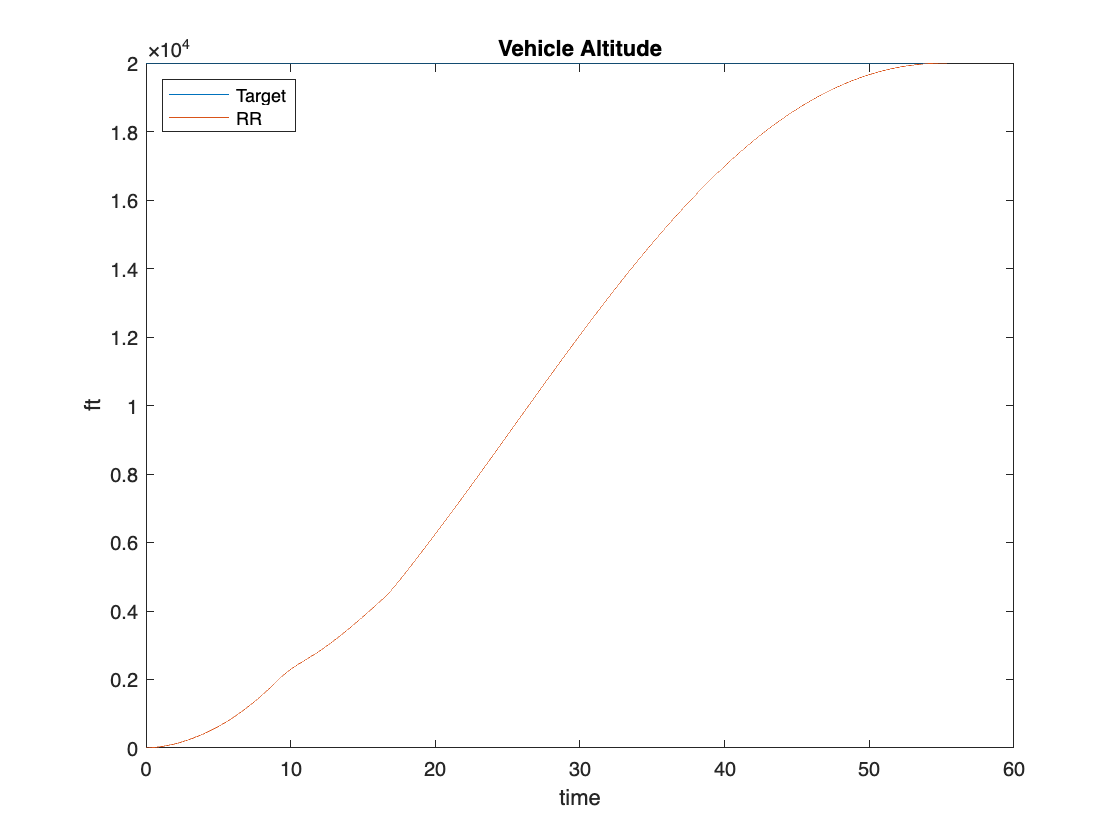

plot(target_sim_out.yout{1}.Values.Time, ...
    target_sim_out.yout{1}.Values.Data(:,[3])'*-1, ...
    target_sim_out.yout{2}.Values.Time, ...
    target_sim_out.yout{2}.Values.Data(:,[3])'*-1);
title('Vehicle Altitude');
xlabel('time');
ylabel("ft");
legend({'Target','RR'},'Location','northwest');

The RR vehicle climbs to 20,000 feet to intercept the target.

### Velocity

% max velocity
max(target_sim_out.yout{5}.Values.Data(:,[1]))

ans = 0.8973

The RR vehicle approaches its max velocity ~ mach 0.9 as it intercepts the target.

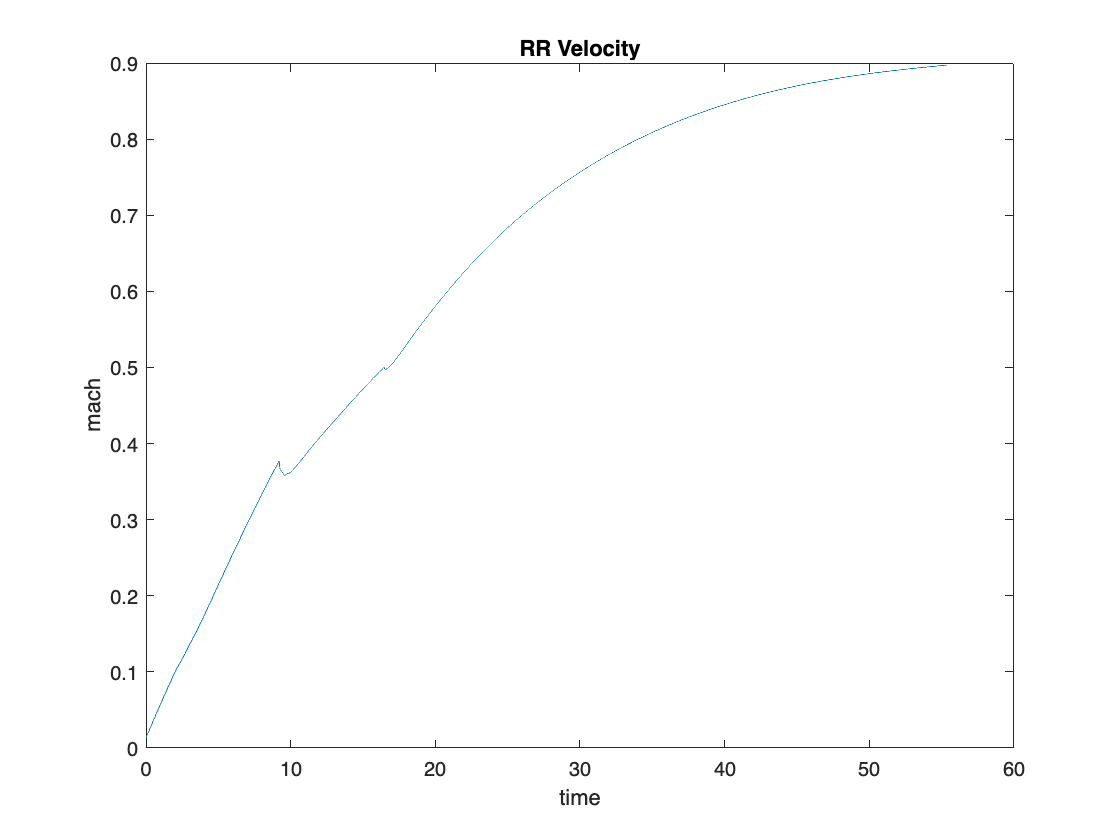

plot(target_sim_out.yout{5}.Values.Time, ...
    target_sim_out.yout{5}.Values.Data(:,[1])');
title('RR Velocity');
xlabel('time');
ylabel("mach");

### Acceleration

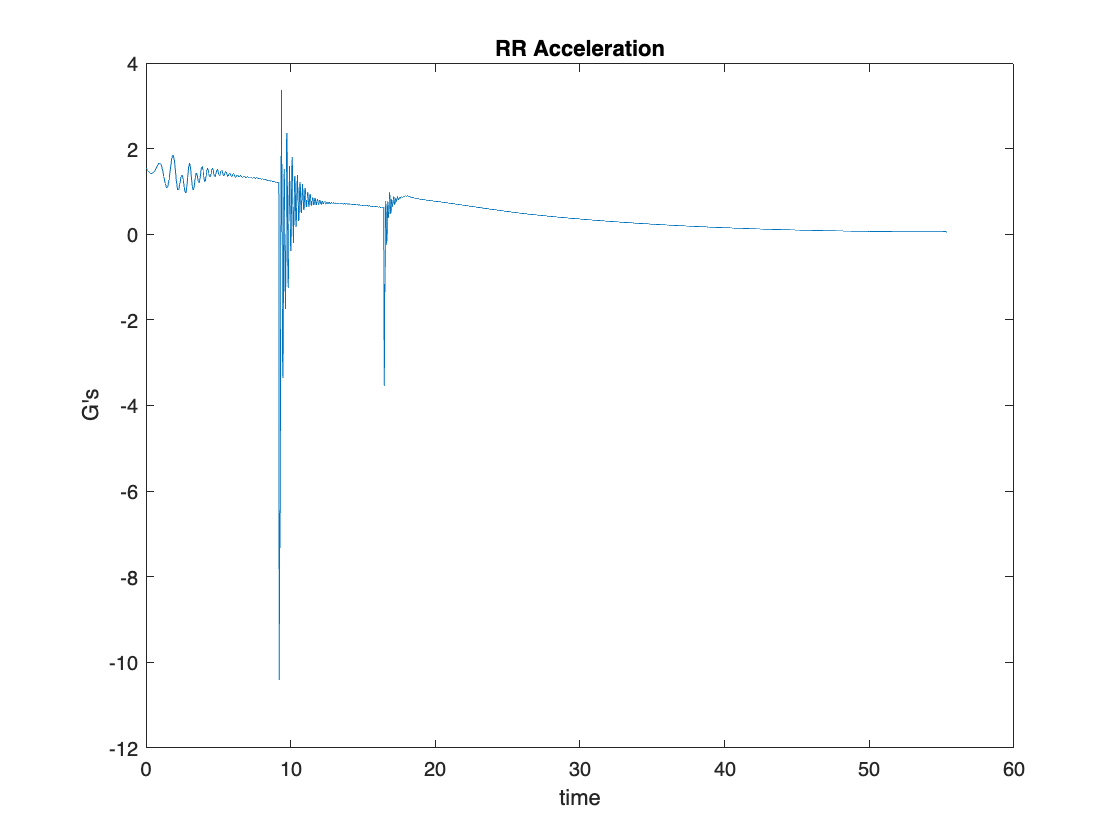

plot(target_sim_out.yout{4}.Values.Time, ...
    target_sim_out.yout{4}.Values.Data(:,[1])'/G);
title('RR Acceleration');
xlabel('time');
ylabel("G's");

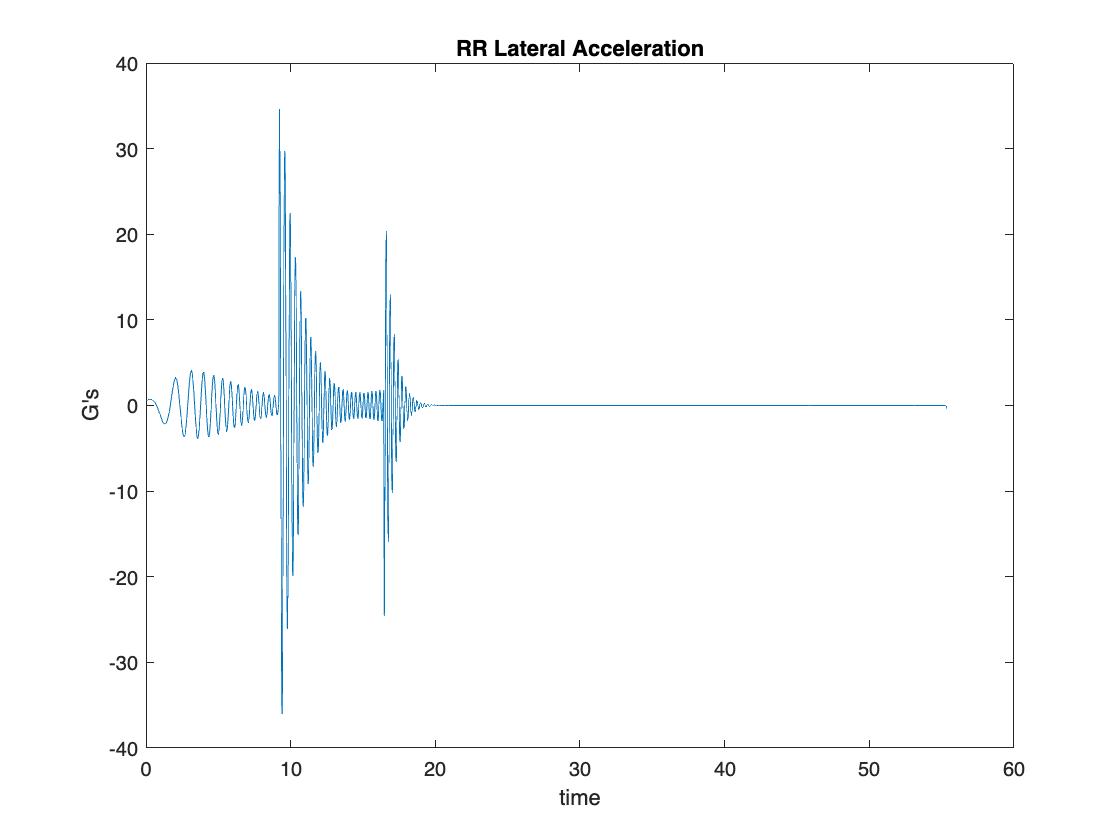

plot(target_sim_out.yout{4}.Values.Time, ...
    target_sim_out.yout{4}.Values.Data(:,[3])'/G);
title('RR Lateral Acceleration');
xlabel('time');
ylabel("G's");

Due to the model simplicity in its control and autopilot design the pitch change commands cause unnecessarily violent G forces on the RR vehicle in this simulation. If more time was available PID rate control and different PID settings for different flight modes like launch, cruise, and target would be added. Additionally, a linear actuator block would have been added to the model to move the elevons. These changes would reduce or eliminate oscillations and limit the G forces. A controller that uses lateral G forces to feed back into pitch control when tracking the target would be explored next.